# Standardize Sequence Lengths

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and corresponding labels.

pathToSignals = "../data/flooddata";
sigds = signalDatastore(pathToSignals, ...
                        "IncludeSubfolders", true, ...
                        "SignalVariableNames", ["ax" "ay" "az"], ...
                        "ReadOutputOrientation", "row");
labels = folders2labels(pathToSignals);
labels = renamecats(labels, ["0.0 ft" "0.19 ft" "2.5 ft" "4.5 ft"]);

This code reads in all the signals in the data set.

sigt = transform(sigds, @prepsig);
sigdata = readall(sigt);

## Task 1

In this activity, you will look at the lengths of all the observations in the flood data set. A quick way to perform on operation on every cell of a cell array is to use a `cellfun`.

To calculate the length of the observations in the data set, you can pass the `length` function to `cellfun` using *function handles*. To create a handle for a function, precede the function name with an `@` sign.

`out` `=` `cellfun``(``@``fun``,``data``)`

sequenceLengths = cellfun(@length, sigdata);

## Task 2

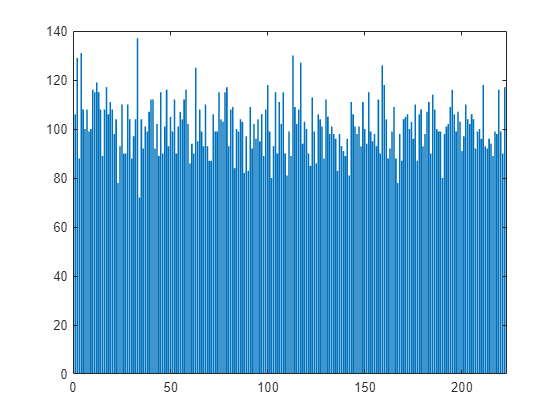

bar(sequenceLengths)

## Task 3

The length of these observations range from about 80 to 120 time steps. While training a deep network, all the signals in a mini-batch need to have the same length.

The shorter signals in the data set will be padded with a constant, like 0, and the longer signals will be truncated. You should choose a length that minimizes the amount of padding and lost data. For this data set, let's use a sequence length of 100.

The `padsequences` function will pad or truncate a signal as needed.

`sig` `=` `padsequences``(``cells``,``dim``,``"Length"``,``L``)`

The second input is the dimension to pad; `1` pads so that the number of rows is equal to `L`, `2` pads so that the number of columns is equal to `L`.

sigpad = padsequences(sigdata, 2, "Length", 100)

sigpad = sigpad(:,:,1) =

   -0.4660   -0.9410    0.6420    1.5270   -0.1540   -0.4380    0.2760   -0.3110   -0.5390   -0.4250    0.1370    0.7740   -0.8080   -1.2800    0.2050    0.3220    0.7800   -0.3940   -0.5670    0.1150   -0.6440   -0.0550   -0.0960    0.5250   -1.2520    0.2330   -0.0590    0.2740    0.4010    0.6580   -1.1540   -0.1280   -0.3260    0.2510    0.2760    0.6020    1.2870    0.0410    0.0150    0.5100    0.2270    0.3910   -1.6260    0.1010    0.1070    0.3400   -0.1340    0.6170    0.2410    0.1870   -0.8180   -0.5090    0.7280   -0.6510   -1.7860   -1.8470   -0.5200   -0.7200   -0.5190    0.1530    1.1790   -1.5230   -0.3990    0.3040   -0.0480   -0.2860   -1.0570   -0.4580    0.6110   -0.1700    0.1440    0.8770    0.5850   -0.5690    0.3410    0.4710    0.2260   -1.6560   -0.4710    0.5920   -0.1000   -0.3150   -0.3160    1.0260   -0.3200   -0.1080    0.9770   -0.3420    0.7710   -0.5970   -0.2730    0.7080   -0.9140   -0.1720    0.2940    0.6040    0.3610    

function sig = prepsig(sigin)
    sig = cell2mat(sigin);
    sig = sig';
    sig = {sig};
end